# Transformata Fouriera sygnałów rzeczywistych

na podstawie indeksu 2a:

N = 1024;
x = randn(1,N);

algorytm:

x1 = x(1:N/2); x2 = x(N/2+1:N);

y = x1 + x2.*1i;

Y = fft(y); %./(N/2);

X = zeros(1,N);

for k=1:N/2
    X(k) = 0.5*(real(Y(k))+real(Y(N/2-k+1)));
    X(k) = 0.5*(imag(Y(k))-imag(Y(N/2-k+1)));
    
    X(N/2+k) = 0.5*(imag(Y(k))+imag(Y(N/2-k+1)));
    X(N/2+k) = 0.5*(real(Y(N/2-k+1))-real(Y(k)));
end

alternatywna wersja (rzeczywista)

Xalter = fft(x);  %./(N);

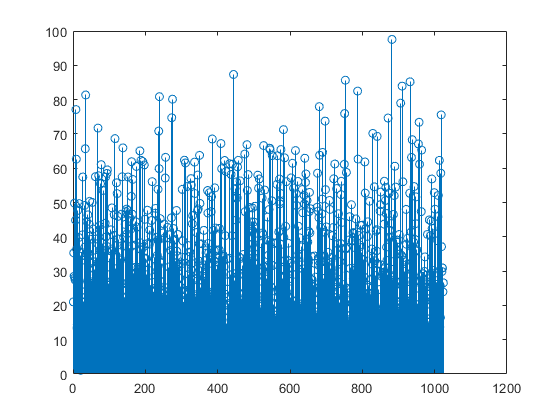


clf
figure
stem(abs(X-Xalter))